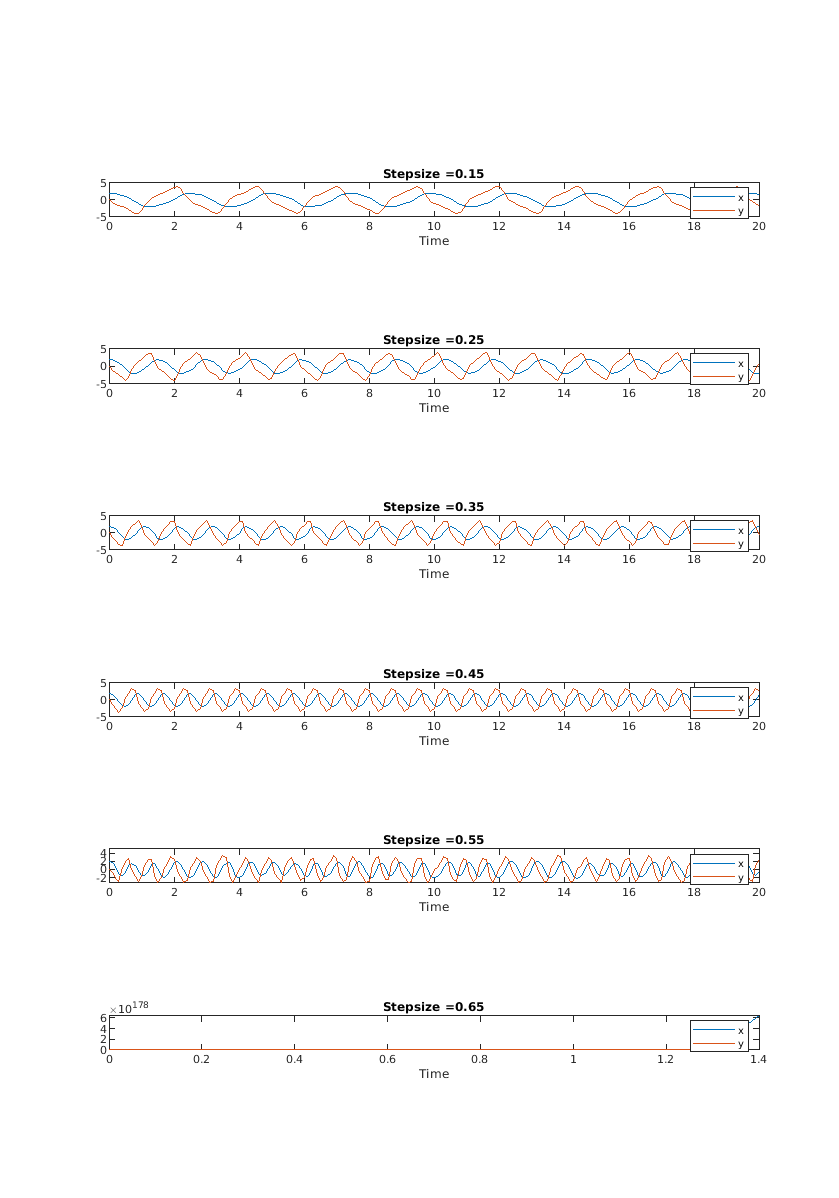

tic
h=[0.1:0.05:0.65]; % stepsize unstable beyond h=0.27
figure1=figure('Position', [100, 100, 7000,10000]);
for j=1:length(h)

u=1;
f = @(x,y) y;
g = @(x,y) u*(1-x^2)*y-3*x;
t=[0:0.1:20]';
l=length(t);
x=zeros(l,2);
x(1,1)=2;
x(1,2)=0;

for i=1:l-1
    k1=zeros(1,2);
    k2=zeros(1,2);
    k3=zeros(1,2);
    k1(1,1) = f(x(i,1),x(i,2));
    k1(1,2) = g(x(i,1),x(i,2));
    
    k2(1,1) = f(x(i,1)+h(j)*k1(1,1)/2,x(i,2)+h(j)*k1(1,2)/2);
    k2(1,2) = g(x(i,1)+h(j)*k1(1,1)/2,x(i,2)+h(j)*k1(1,2)/2);
    
    k3(1,1) = f(x(i,1)-h(j)*k1(1,1)+2*h(j)*k2(1,1),x(i,2)-h(j)*k1(1,2)+2*h(j)*k2(1,2));
    k3(1,2) = g(x(i,1)-h(j)*k1(1,1)+2*h(j)*k2(1,1),x(i,2)-h(j)*k1(1,2)+2*h(j)*k2(1,2));
    x(i+1,:) = x(i,:) + (h(j)/6)*(k1+4*k2+k3);
end
if rem(j,2)==0
subplot(length(h),1,j);
plot(t,x)
title("Stepsize ="+h(j))
xlabel('Time')
legend('x','y')
end

end

timetaken_stepsize_vary=toc

timetaken_stepsize_vary = 0.6591